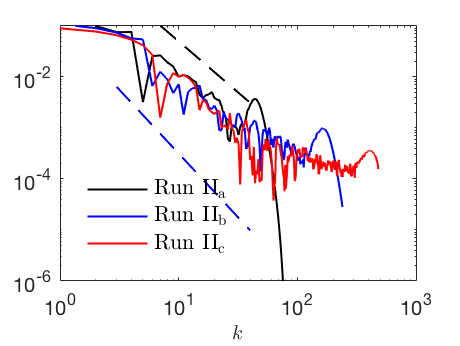

%spectrum
%old one 1) -3/2  -4 2) -3/2 3) -5/2 4) -5/2 
%new one all use -5/2 and -2
clear;
load c_spectrum.mat;

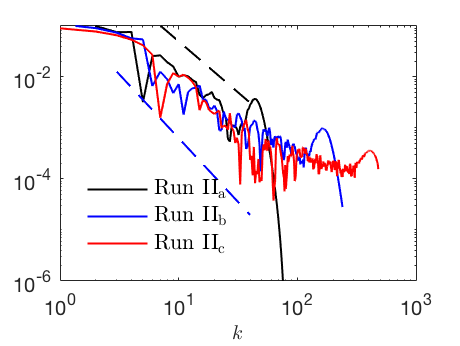

testx1=(3:40);
testx1=testx1';
testy1=testx1.^(-5/2);
testy1=testy1/5;

testx2 = (3:40);
testx2=testx2';
testy2=5*testx2.^(-2);



smoothed_cas_256 = smoothdata(cavr_norm256+c0avr_norm256, 'sgolay');
smoothed_cas_512 = smoothdata(cavr_norm512+c0avr_norm512, 'sgolay');
smoothed_cas_1024 = smoothdata(cavr_norm1024+c0avr_norm1024, 'sgolay');

car256spec  = calcSpec(smoothed_cas_256);
car512spec  = calcSpec(smoothed_cas_512);
car1024spec  = calcSpec(smoothed_cas_1024);

% k1 = 1:length(car256spec);
% smoothed_k1 = k1(car256spec>0);
% k2 = 1:length(car512spec);
% smoothed_k2 = k2(car512spec>0);
% k3 = 1:length(car1024spec);
% smoothed_k3 = k3(car1024spec>0);
% 
% 
% loglog(smoothed_k1, car256spec(car256spec>0),'k'); hold on;
% loglog(smoothed_k2, car512spec(car512spec>0),'b');
% loglog(smoothed_k3, car1024spec(car1024spec>0),'r'); 

loglog(abs(car256spec),'k'); hold on;
loglog(abs(car512spec),'b');
loglog(abs(car1024spec),'r'); 

loglog(testx1, testy1,'b--'); %hold off;
loglog(testx2, testy2,'k--'); hold off;

fig = gcf;
%legend_handle=legend('{Run $\rm I_c$}','{Run $\rm II_c$}','{Run $\rm III_c$}','{Run $\rm IV_c$}','Location', 'Best');
legend_handle=legend('{Run $\rm II_a$}','{Run $\rm II_b$}','{Run $\rm II_c$}','Location', 'Best');
set(legend_handle,'Interpreter','latex','fontsize',11,'location','southwest')
xlabel('$k$','Interpreter','latex','fontsize',10)
%ylabel('$C(k)^{ub}$','Interpreter','latex','fontsize',10)

set(gcf,'WindowStyle','normal');
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
set(gca,'ylabel',[]);
set(gcf,'WindowStyle','normal')
ylim([10^-6 10^-1])
xlabel('$k$','FontSize',10,'Interpreter','latex')
set(findall(gca, 'Type', 'Line'),'LineWidth',1.0);
legend boxoff;

save c_spectrum;